# SRIR Subspace Decomposition: Influence of the Parameters

**This live script demonstrates how to choose suitable decomposition parameters. It is available at **[**https://github.com/thomasdeppisch/SRIR-Subspace-Decomposition.**](https://github.com/thomasdeppisch/SRIR-Subspace-Decomposition)

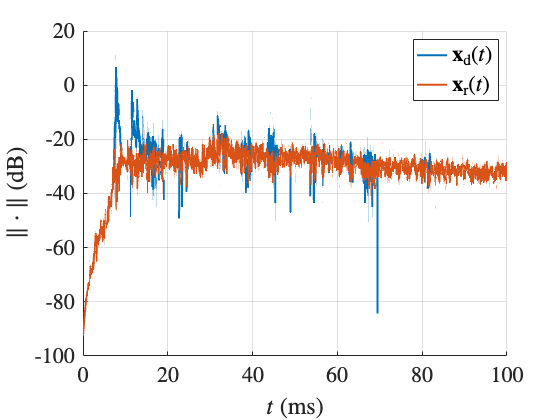

% load a measured SRIR
srirStruct = load('resources/TA_lecture_hall_em32_ACN_N3D.mat');
srir = srirStruct.srir;
fs = srirStruct.fs;

% first, do the decomposition with default parameters:
% blockLenSmp = 32, noiseAnalysisTimeMs = 20, numBlocksGsvSumAvg = 32, kappa = 3;
[dirSrir, resSrir, numDirSubspaceComponents, gsvs, detectionThreshold,...
    gsvSum, avgGsvSum] = srirSubspaceDecomp(srir, fs);

%% plot
srirLen = size(srir,1);
t = linspace(0, srirLen/fs-1/fs, srirLen).';
hopSizeSmp = 4;
tBlocks = (0:hopSizeSmp:size(gsvs,1)*hopSizeSmp-hopSizeSmp)/fs;

% plot the direct part and the residual over time
figure
hold on
plot(t*1000, db(sum(abs(dirSrir), 2)), 'LineWidth', 2)
plot(t*1000, db(sum(abs(resSrir), 2)), 'LineWidth', 2)
xlim([0,100])
xlabel('$t$ (ms)')
ylabel('$\| \cdot \|$ (dB)')
legend('$\mathbf{x}_\mathrm{d}(t)$', '$\mathbf{x}_\mathrm{r}(t)$')
grid on

**In this case, the results after using the default parameters already look promising. The direct sound and strong early reflections are clearly separated from the residual. The residual norm does not fluctuate strongly, it does not contain large peaks. We get a deeper insight into the results by looking at the evolution of the generalized singular values (GSVs), the reflection detection threshold, and the subspace component threshold below.**

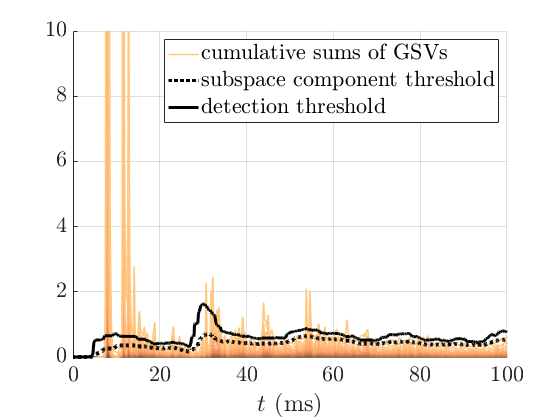

numChannels = size(srir,2);
cumsumGSVsColors = copper(numChannels);
cumsumGSVs = cumsum(gsvs,2);

% plot evolution of GSVs and thresholds
figure
hold on
for ii = 1:numChannels
    if ii == numChannels
        hGSVCumsum = plot(tBlocks*1000, cumsumGSVs(:,ii), ...
            'Color', cumsumGSVsColors(ii,:), 'LineWidth', 1.5);
    else
        plot(tBlocks*1000, cumsumGSVs(:,ii)*numChannels/ii, ...
            'Color', cumsumGSVsColors(ii,:), 'LineWidth', 1.5)
    end
end
hAvgGSVs = plot(tBlocks*1000, avgGsvSum, 'k:');
hDetectionThresh = plot(tBlocks*1000, detectionThreshold, 'k');
grid on
xlabel('$t$ (ms)')
xlim([0,100])
ylim([0,10])
legend([hGSVCumsum, hAvgGSVs, hDetectionThresh], 'cumulative sums of GSVs', ...
    'subspace component threshold', 'detection threshold')

**Note that this figure (and the following figures showing the GSV sums and thresholds) is supposed to be read from right to left as this is the way the algorithm proceeds: it first takes a block from the end of the SRIR as initial residual estimate and then proceeds toward the beginning of the SRIR.**

**Energetic peaks, as we expect to be generated by reflections, are emphasized in the GSVs. Whenever the sum of the GSVs exceeds the detection threshold, the subspace decomposition is performed. The number of direct subspace components is defined as the number of cumulative GSV sums above the subspace component threshold. The above figure shows that the detection threshold is only exceeded if strong peaks in the GSV sums are present. The subspace component threshold changes smoothely over time, it is not strongly influenced by the reflections, which shows that the amount of averaging was chosen well.**

**Below, we demonstrate what happens if parameters are chosen that are less suitable for this SRIR.**

## **Influence of the Block Size**

**The block size in samples needs to be equal to or larger than the number of microphones (or more generally the number of signal channels). Let's increase the block size from 32 samples to 64 samples.**

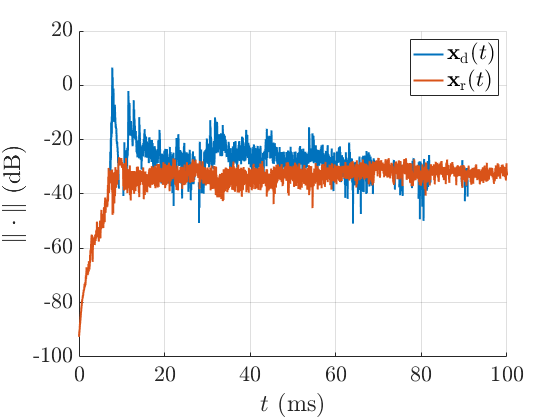

blockLenSmp = 64;

[dirSrir, resSrir, numDirSubspaceComponents, gsvs, detectionThreshold,...
    gsvSum, avgGsvSum] = srirSubspaceDecomp(srir, fs, blockLenSmp);

hopSizeSmp = round(blockLenSmp/8);
tBlocks = (0:hopSizeSmp:size(gsvs,1)*hopSizeSmp-hopSizeSmp)/fs;

% plot the direct part and the residual over time
figure
hold on
plot(t*1000, db(sum(abs(dirSrir), 2)), 'LineWidth', 2)
plot(t*1000, db(sum(abs(resSrir), 2)), 'LineWidth', 2)
xlim([0,100])
xlabel('$t$ (ms)')
ylabel('$\| \cdot \|$ (dB)')
legend('$\mathbf{x}_\mathrm{d}(t)$', '$\mathbf{x}_\mathrm{r}(t)$')
grid on

**After increasing the block size, the direct part contains not only individual peaks, but it contains a large part of the energy of the early response. To get insights on why this is happening, we again analyze the GSV sums below.**

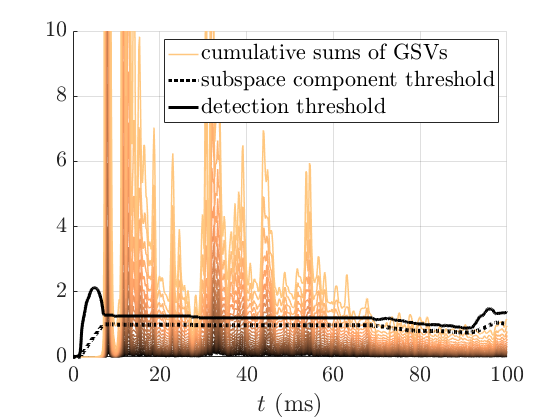

cumsumGSVs = cumsum(gsvs,2);

% plot evolution of GSVs and thresholds
figure
hold on
for ii = 1:numChannels
    if ii == numChannels
        hGSVCumsum = plot(tBlocks*1000, cumsumGSVs(:,ii), ...
            'Color', cumsumGSVsColors(ii,:), 'LineWidth', 1.5);
    else
        plot(tBlocks*1000, cumsumGSVs(:,ii)*numChannels/ii, ...
            'Color', cumsumGSVsColors(ii,:), 'LineWidth', 1.5)
    end
end
hAvgGSVs = plot(tBlocks*1000, avgGsvSum, 'k:');
hDetectionThresh = plot(tBlocks*1000, detectionThreshold, 'k');
grid on
xlabel('$t$ (ms)')
xlim([0,100])
ylim([0,10])
legend([hGSVCumsum, hAvgGSVs, hDetectionThresh], 'cumulative sums of GSVs', ...
    'subspace component threshold', 'detection threshold')

**Due to the larger block size, GSVs are calculated with poorer temporal resolution. In consequence, the overall sum of the GSVs increases strongly in the early part of the response and the detection threshold is exceeded for the full first 70 ms of the response. If the larger block size is needed (e.g., in case more microphones are used), we can counteract by modifying the detection threshold. (See below.)**

## Influence of the Detection-Threshold Offset Kappa

**Let's increase the detection threshold offset kappa to 4 standard deviations (instead of the 3 standard deviations used above) to see if we can counteract the increased block size.**

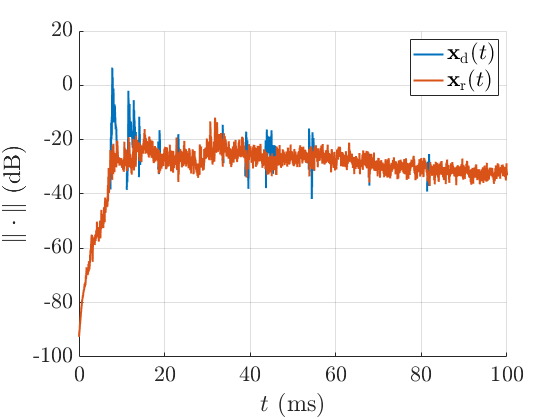

blockLenSmp = 64;
hopSizeSmp = round(blockLenSmp/8);
kappa = 4;

[dirSrir, resSrir, numDirSubspaceComponents, gsvs, detectionThreshold, ...
    gsvSum, avgGsvSum] = srirSubspaceDecomp(srir, fs, blockLenSmp, hopSizeSmp, kappa);

tBlocks = (0:hopSizeSmp:size(gsvs,1)*hopSizeSmp-hopSizeSmp)/fs;

% plot the direct part and the residual over time
figure
hold on
plot(t*1000, db(sum(abs(dirSrir), 2)), 'LineWidth', 2)
plot(t*1000, db(sum(abs(resSrir), 2)), 'LineWidth', 2)
xlim([0,100])
xlabel('$t$ (ms)')
ylabel('$\| \cdot \|$ (dB)')
legend('$\mathbf{x}_\mathrm{d}(t)$', '$\mathbf{x}_\mathrm{r}(t)$')
grid on

**The decomposition was successful again, individual reflections are extracted from the SRIR. However, less reflections are extracted than when running the decomposition with default parameters (see first figure). We see the reason for this when analyzing the sum of the GSVs and the thresholds below.**

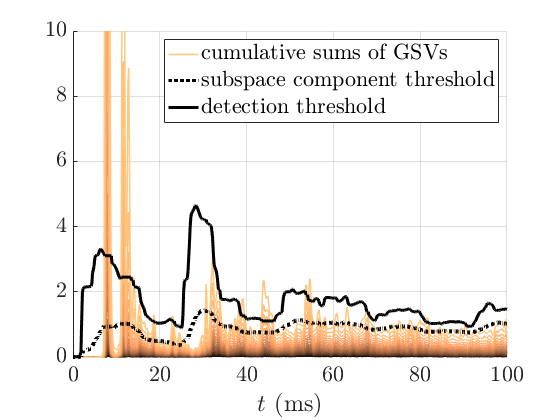

cumsumGSVs = cumsum(gsvs,2);

% plot evolution of GSVs and thresholds
figure
hold on
for ii = 1:numChannels
    if ii == numChannels
        hGSVCumsum = plot(tBlocks*1000, cumsumGSVs(:,ii), ...
            'Color', cumsumGSVsColors(ii,:), 'LineWidth', 1.5);
    else
        plot(tBlocks*1000, cumsumGSVs(:,ii)*numChannels/ii, ...
            'Color', cumsumGSVsColors(ii,:), 'LineWidth', 1.5)
    end
end
hAvgGSVs = plot(tBlocks*1000, avgGsvSum, 'k:');
hDetectionThresh = plot(tBlocks*1000, detectionThreshold, 'k');
grid on
xlabel('$t$ (ms)')
xlim([0,100])
ylim([0,10])
legend([hGSVCumsum, hAvgGSVs, hDetectionThresh], 'cumulative sums of GSVs', ...
    'subspace component threshold', 'detection threshold')

#### **We observe that the reflections are extracted more selectively, e.g., the peaks around t = 30 ms are below the detection threshold, because the detection threshold changes quite strongly with strong reflections. We can smooth the detection threshold by averaging over a larger number of blocks. Let's investigate that below.**

## Influence of the Number of Blocks for Averaging the GSVs (in the Calculation of the Thresholds)

**The amount of averaging of the GSVs influences the calculation of the detection threshold and the subspace component threshold. Less averaging makes the thresholds react faster to changes in residual energy, more averaging yields smoother thresholds. Let's increase the averaging of the GSVs from 32 blocks to 48 blocks.**

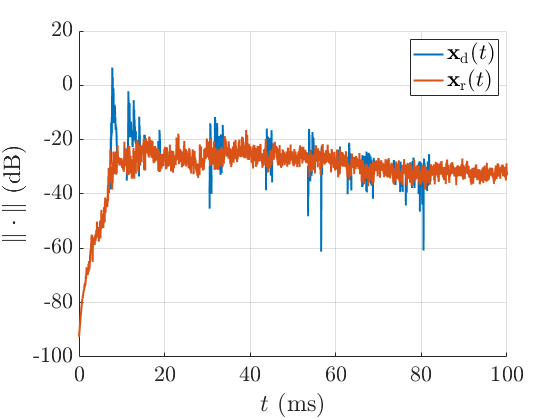

blockLenSmp = 64;
hopSizeSmp = round(blockLenSmp/8);
kappa = 3;
numBlocksGsvSumAvg = 48; % the default value used above was 32 blocks

[dirSrir, resSrir, numDirSubspaceComponents, gsvs, detectionThreshold, ...
    gsvSum, avgGsvSum] =  srirSubspaceDecomp(srir, fs, blockLenSmp, ...
    hopSizeSmp, kappa, numBlocksGsvSumAvg);

tBlocks = (0:hopSizeSmp:size(gsvs,1)*hopSizeSmp-hopSizeSmp)/fs;

% plot the direct part and the residual over time
figure
hold on
plot(t*1000, db(sum(abs(dirSrir), 2)), 'LineWidth', 2)
plot(t*1000, db(sum(abs(resSrir), 2)), 'LineWidth', 2)
xlim([0,100])
xlabel('$t$ (ms)')
ylabel('$\| \cdot \|$ (dB)')
legend('$\mathbf{x}_\mathrm{d}(t)$', '$\mathbf{x}_\mathrm{r}(t)$')
grid on

**Again, more reflections are detected, e.g. the ones around t = 30 ms.**

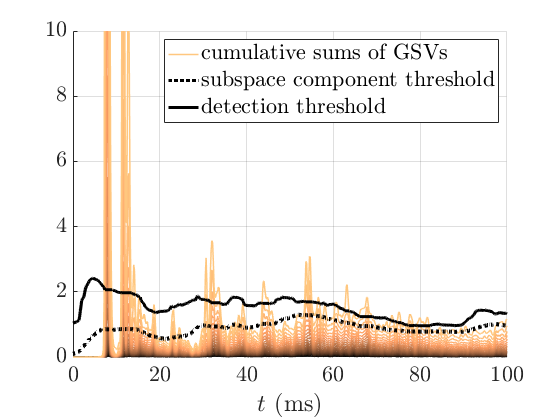

cumsumGSVs = cumsum(gsvs,2);

% plot evolution of GSVs and thresholds
figure
hold on
for ii = 1:numChannels
    if ii == numChannels
        hGSVCumsum = plot(tBlocks*1000, cumsumGSVs(:,ii), ...
            'Color', cumsumGSVsColors(ii,:), 'LineWidth', 1.5);
    else
        plot(tBlocks*1000, cumsumGSVs(:,ii)*numChannels/ii, ...
            'Color', cumsumGSVsColors(ii,:), 'LineWidth', 1.5)
    end
end
hAvgGSVs = plot(tBlocks*1000, avgGsvSum, 'k:');
hDetectionThresh = plot(tBlocks*1000, detectionThreshold, 'k');
grid on
xlabel('$t$ (ms)')
xlim([0,100])
ylim([0,10])
legend([hGSVCumsum, hAvgGSVs, hDetectionThresh], 'cumulative sums of GSVs', ...
    'subspace component threshold', 'detection threshold')

#### **The detection and subspace component thresholds are much smoother again, they are not influenced so strongly by individual reflections anymore.**

## Influence of the Length of the Residual Estimate

**The residual estimate faciliates an implicit pre-whitening of the residual. As the residual estimate is updated whenever no reflection is detected, it adapts to changes of the residual, e.g., changes in intensity or directional properties. In our tests, a 20 ms residual estimate most often yielded good results. Below, we will show what happens if much shorter or much longer residual estimates are used.**

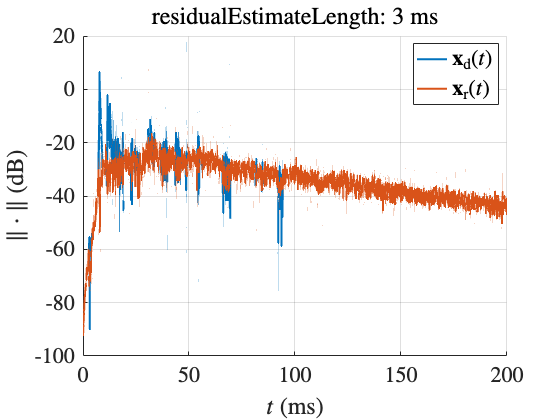

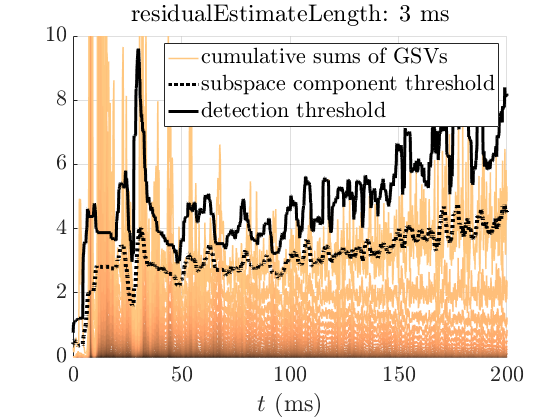

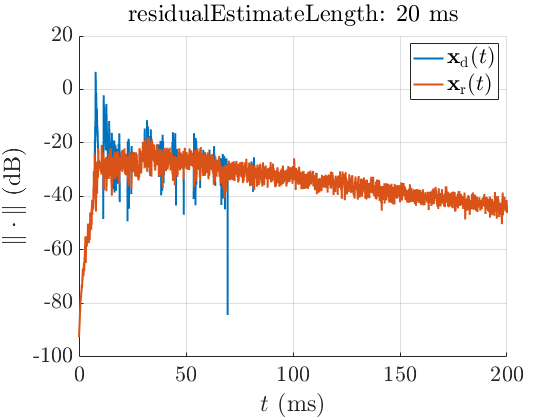

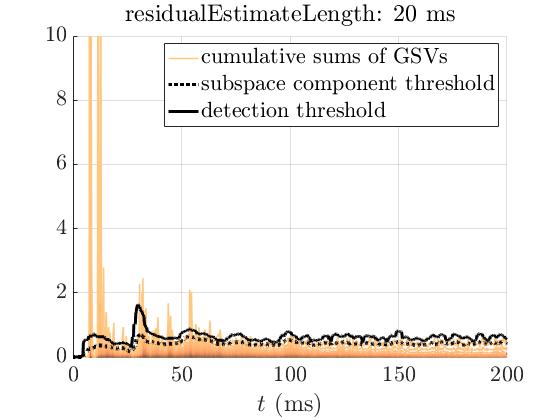

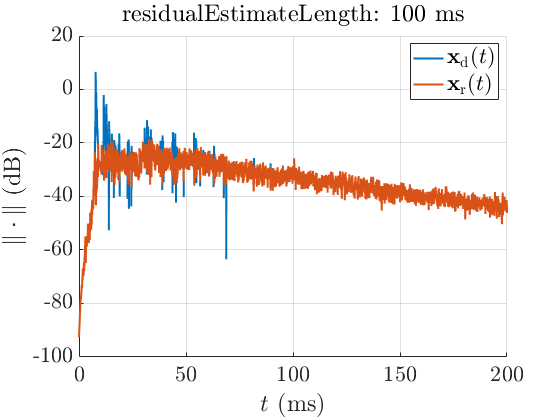

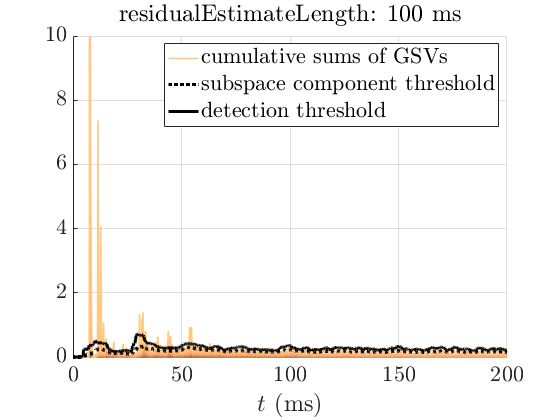

blockLenSmp = 32;
hopSizeSmp = round(blockLenSmp/8);
kappa = 3;
numBlocksGsvSumAvg = 32;
residualEstimateLengthMs = [3, 20, 100];

for rr = 1:length(residualEstimateLengthMs)
    [dirSrir, resSrir, numDirSubspaceComponents, gsvs, detectionThreshold,...
        gsvSum, avgGsvSum] = srirSubspaceDecomp(srir, fs, blockLenSmp, hopSizeSmp, ...
        kappa, numBlocksGsvSumAvg, residualEstimateLengthMs(rr));
    
    tBlocks = (0:hopSizeSmp:size(gsvs,1)*hopSizeSmp-hopSizeSmp)/fs;
    
    % plot the direct part and the residual over time
    figure
    hold on
    plot(t*1000, db(sum(abs(dirSrir), 2)), 'LineWidth', 2)
    plot(t*1000, db(sum(abs(resSrir), 2)), 'LineWidth', 2)
    xlim([0,200])
    xlabel('$t$ (ms)')
    ylabel('$\| \cdot \|$ (dB)')
    legend('$\mathbf{x}_\mathrm{d}(t)$', '$\mathbf{x}_\mathrm{r}(t)$')
    grid on
    title(['residualEstimateLength: ' num2str(residualEstimateLengthMs(rr)) ' ms'])
    cumsumGSVs = cumsum(gsvs,2);
    
    % plot evolution of GSVs and thresholds
    figure
    hold on
    for ii = 1:numChannels
        if ii == numChannels
            hGSVCumsum = plot(tBlocks*1000, cumsumGSVs(:,ii), ...
                'Color', cumsumGSVsColors(ii,:), 'LineWidth', 1.5);
        else
            plot(tBlocks*1000, cumsumGSVs(:,ii)*numChannels/ii, ...
                'Color', cumsumGSVsColors(ii,:), 'LineWidth', 1.5)
        end
    end
    hAvgGSVs = plot(tBlocks*1000, avgGsvSum, 'k:');
    hDetectionThresh = plot(tBlocks*1000, detectionThreshold, 'k');
    grid on
    xlabel('$t$ (ms)')
    xlim([0,200])
    ylim([0,10])
    title(['residualEstimateLength: ' num2str(residualEstimateLengthMs(rr)) ' ms'])
    legend([hGSVCumsum, hAvgGSVs, hDetectionThresh], 'cumulative sums of GSVs', ...
        'subspace component threshold', 'detection threshold')
end

#### **If the residual estimate is chosen to short (top two figures), the implicit pre-whitening of the residual does not work and the GSV sums are not constant in the absence of salient reflections. If the residual estimate length is appropriate (middle two figures), the GSV sums do not change strongly in magnitude and reflections create clearly visible peaks in the GSV sums. If the length is chosen very long (bottom two figures), the GSV sums are reduced in magnitude and the decomposition will only work if the other parameters are chosen optimally. Note that in all cases, we limited the subspace decomposition to the early part of the SRIR up until t = 100 ms.**